%% Preprocessing and Filtering
clc; clear; close all;

% Load data
data_file = 'Data_Shariftabar_Nouri.mat';
load(data_file); 

num_channels = size(channels_data, 1);
num_trials = size(channels_data, 2);
fprintf('[Preprocessing] Data loaded. %d channels, %d trials.\n', num_channels, num_trials);

[Preprocessing] Data loaded. 4 channels, 10 trials.



% Set sampling frequency
fs = 2000; 
fprintf('[Preprocessing] fs = %d Hz\n', fs);

[Preprocessing] fs = 2000 Hz



% Design 50Hz Notch filter
wo = 50/(fs/2);  
bw = wo/35;
[b_notch, a_notch] = iirnotch(wo, bw);

% Design 1Hz Butterworth high-pass filter (order 1)
fc_hp = 1; 
[b_hp, a_hp] = butter(1, fc_hp/(fs/2), 'high');

% Initialize filtered data cell array
filtered_data = cell(num_channels, num_trials);

for ch = 1:num_channels
    for tr = 1:num_trials
        % Extract raw signal
        raw_sig = channels_data{ch, tr}.data;
        
        % Apply Notch filter
        sig_notch = filtfilt(b_notch, a_notch, raw_sig);
        
        % Apply high-pass filter
        sig_filtered = filtfilt(b_hp, a_hp, sig_notch);
        
        % Store filtered signal
        filtered_data{ch, tr}.data = sig_filtered;
        
        % Keep comments if available
        if isfield(channels_data{ch, tr}, 'comments')
            filtered_data{ch, tr}.comments = channels_data{ch, tr}.comments;
        end
    end
end
fprintf('[Preprocessing] Filters applied to all channels.\n');

[Preprocessing] Filters applied to all channels.


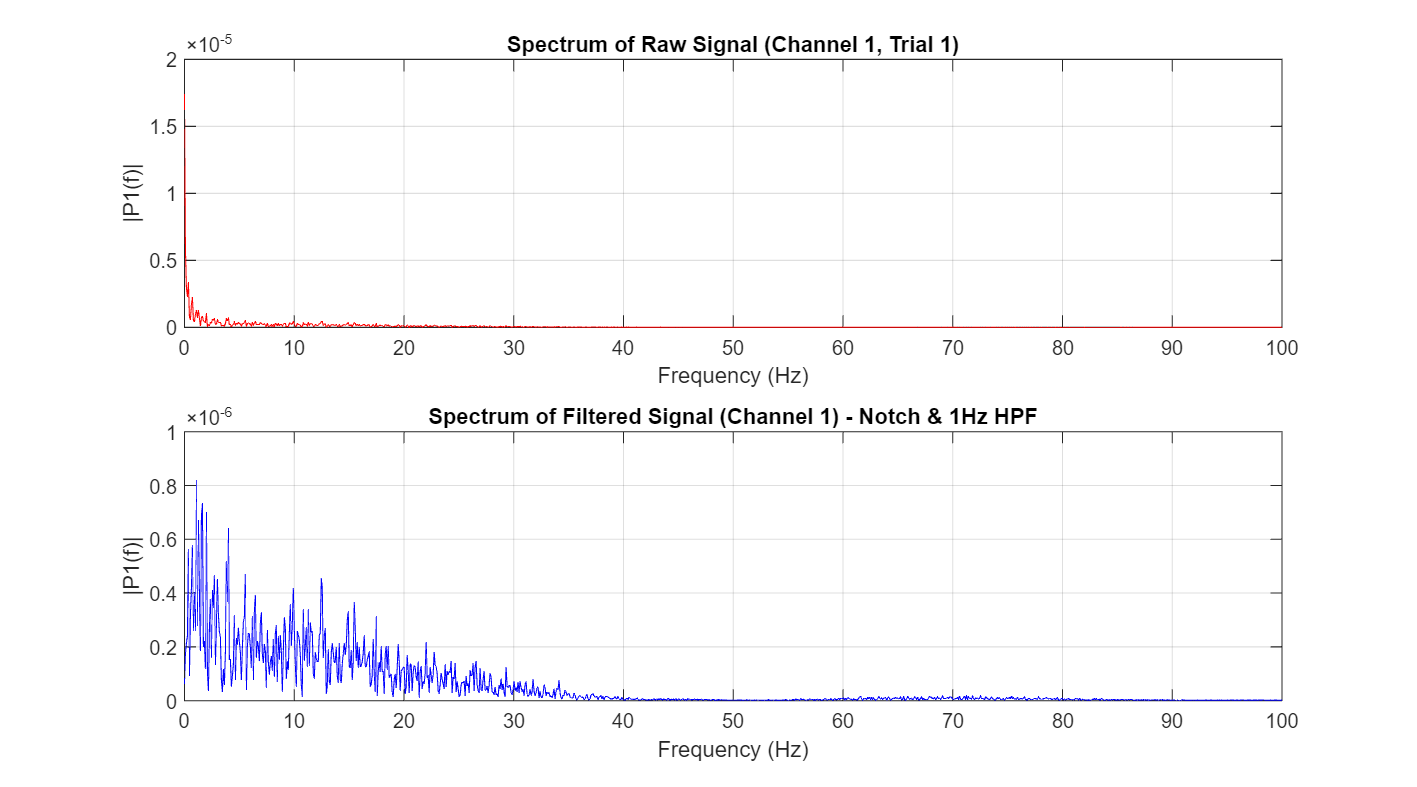

[Part A] Spectrum plotted for Channel 1.


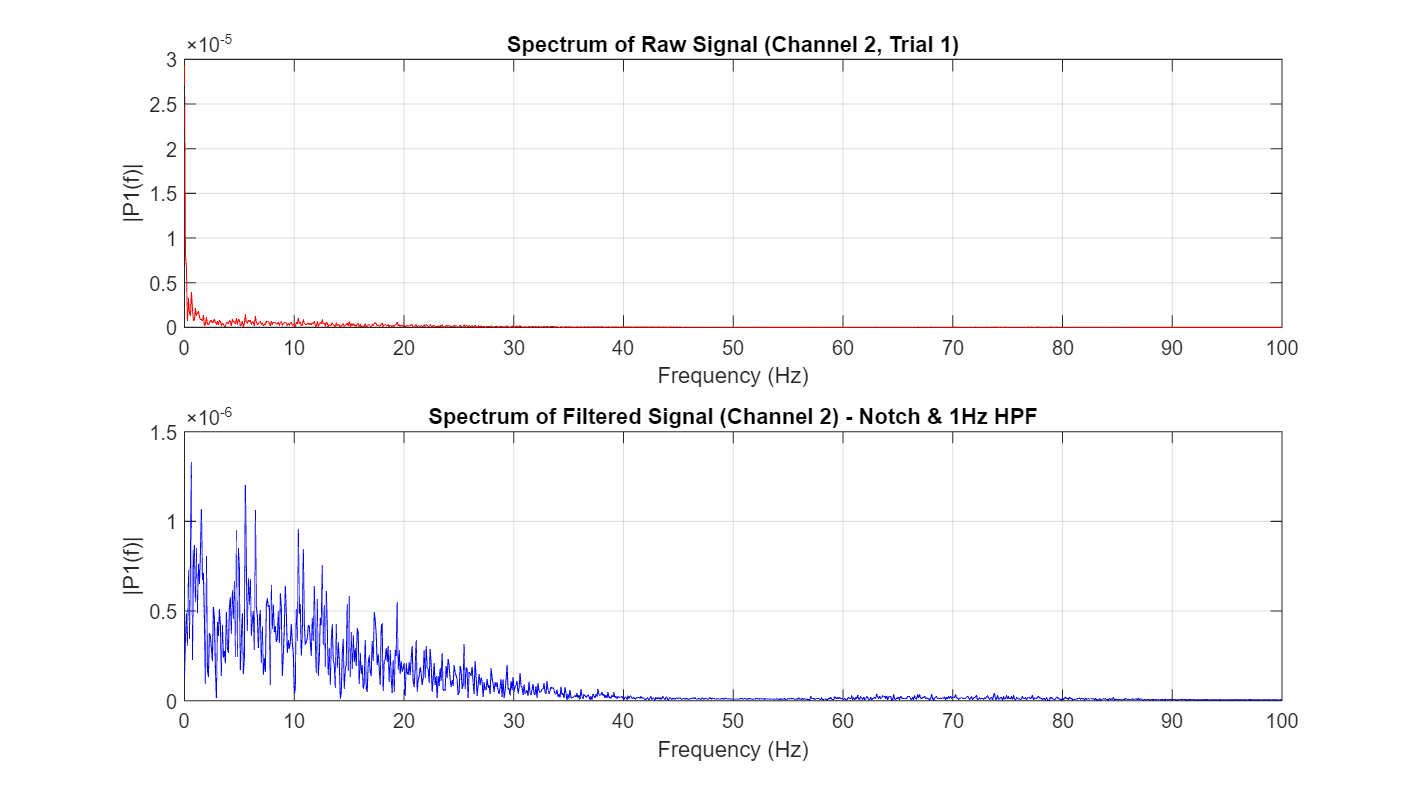

[Part A] Spectrum plotted for Channel 2.


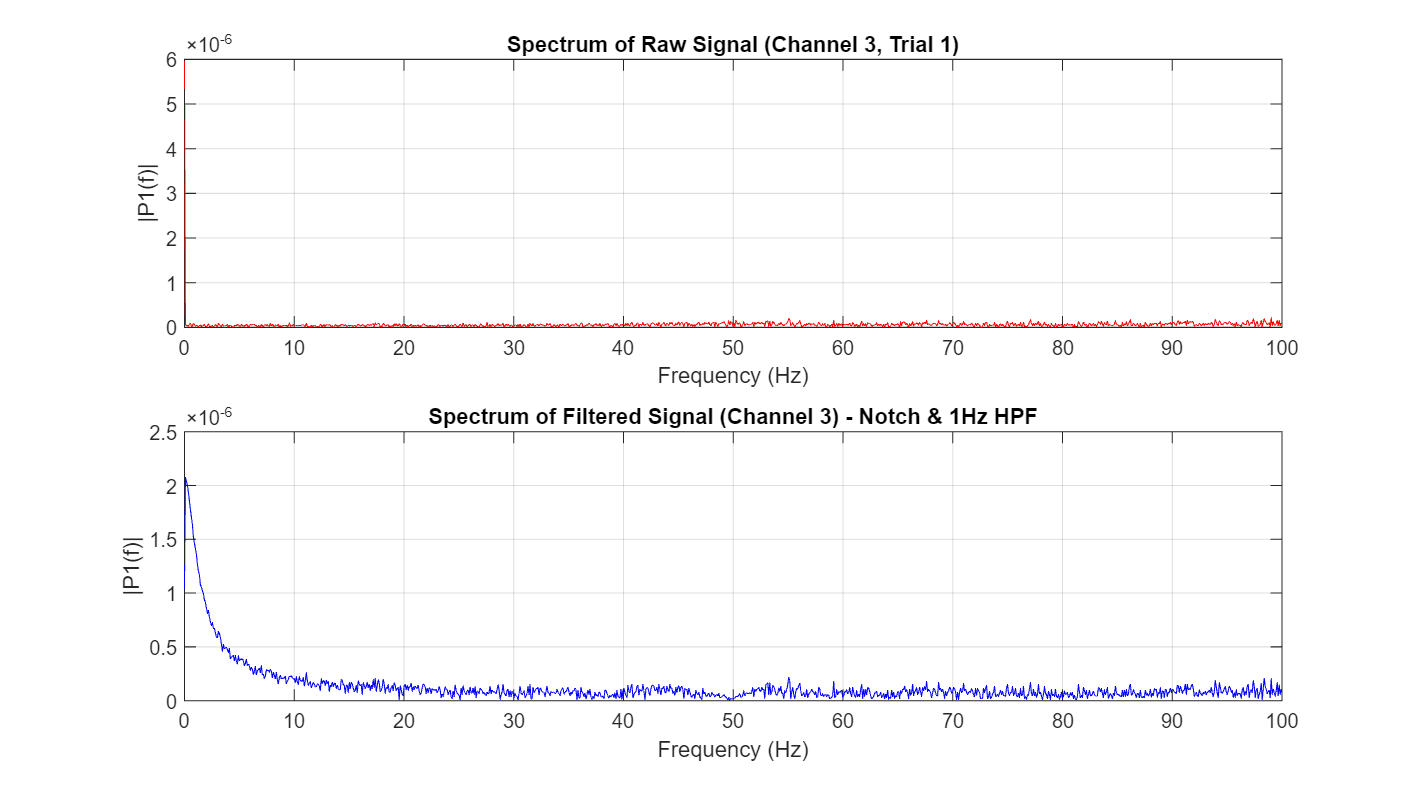

[Part A] Spectrum plotted for Channel 3.


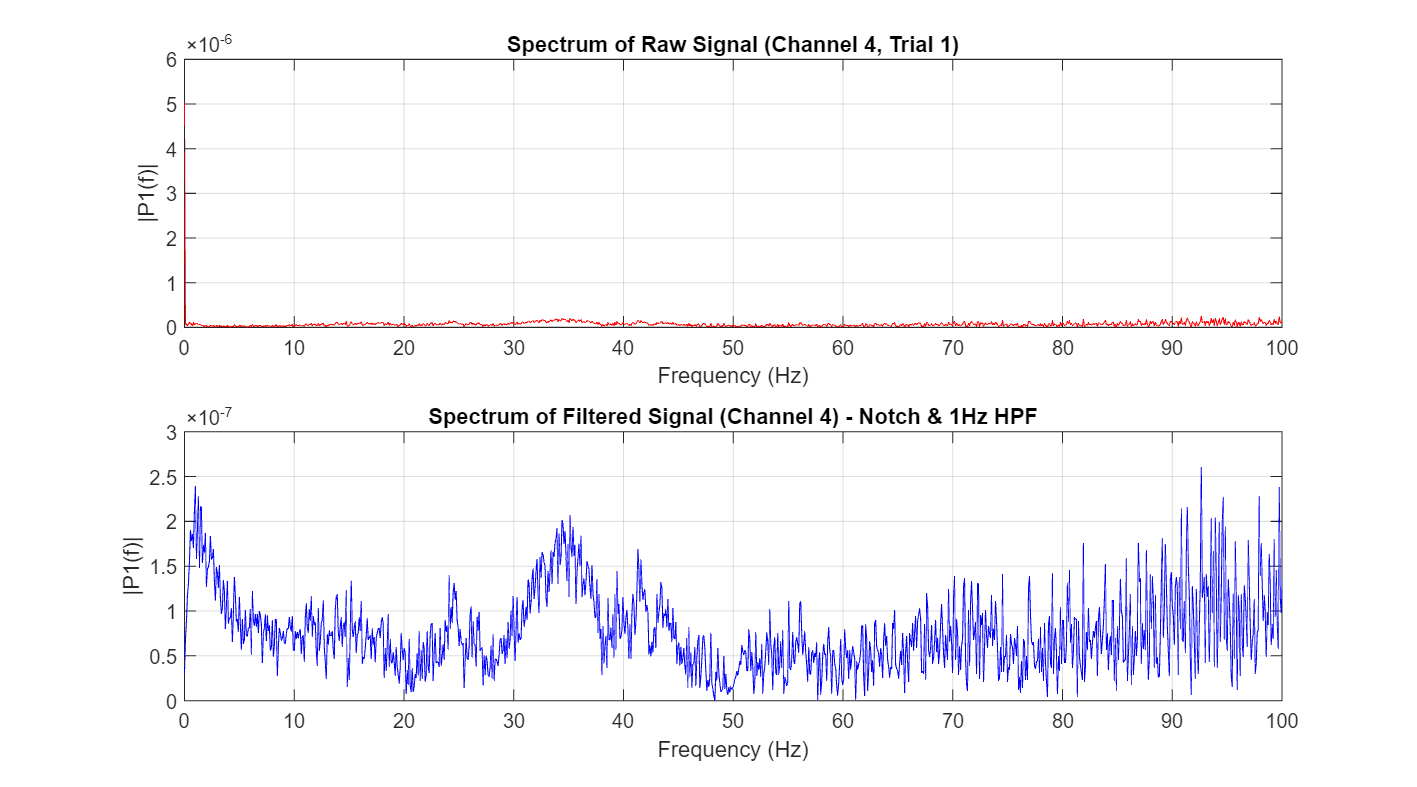

[Part A] Spectrum plotted for Channel 4.


%% Part A: Plot Spectrum (Before and After Filtering for All 4 Channels)
% Select Trial 1 for demonstration
tr_idx = 1;

for ch_idx = 1:num_channels
    % Extract raw and filtered data for current channel
    raw_demo = channels_data{ch_idx, tr_idx}.data;
    filt_demo = filtered_data{ch_idx, tr_idx}.data;
    
    % Signal length
    L = length(raw_demo);
    
    % Compute FFT for raw signal
    fft_raw = fft(raw_demo);
    P2_raw = abs(fft_raw / L);
    P1_raw = P2_raw(1:floor(L/2)+1);
    P1_raw(2:end-1) = 2 * P1_raw(2:end-1);
    
    % Compute FFT for filtered signal
    fft_filt = fft(filt_demo);
    P2_filt = abs(fft_filt / L);
    P1_filt = P2_filt(1:floor(L/2)+1);
    P1_filt(2:end-1) = 2 * P1_filt(2:end-1);
    
    % Frequency vector
    f = fs * (0:(floor(L/2))) / L;
    
    % Plot Spectrum
    figure('Name', sprintf('Part A: Spectrum Ch %d', ch_idx), 'Color', 'w', 'Position', [100, 100, 900, 500]);
    
    % Raw Signal Spectrum
    subplot(2,1,1);
    plot(f, P1_raw, 'r');
    title(sprintf('Spectrum of Raw Signal (Channel %d, Trial 1)', ch_idx));
    xlabel('Frequency (Hz)');
    ylabel('|P1(f)|');
    xlim([0 100]); % Zoom in to see 50 Hz and low frequencies
    grid on;
    
    % Filtered Signal Spectrum
    subplot(2,1,2);
    plot(f, P1_filt, 'b');
    title(sprintf('Spectrum of Filtered Signal (Channel %d) - Notch & 1Hz HPF', ch_idx));
    xlabel('Frequency (Hz)');
    ylabel('|P1(f)|');
    xlim([0 100]);
    grid on;
    
    fprintf('[Part A] Spectrum plotted for Channel %d.\n', ch_idx);
end

%% Part B: Train/Test Split and Normalization
% Split trials: 80% Train (Trials 1-8), 20% Test (Trials 9-10)
train_trials = 1:8;
test_trials = 9:10;

fprintf('\n[Part B] Splitting data: Trials 1-8 for Training, Trials 9-10 for Testing.\n');


[Part B] Splitting data: Trials 1-8 for Training, Trials 9-10 for Testing.


fprintf('[Part B] Normalization Method: Z-score (Mean=0, Variance=1)\n');

[Part B] Normalization Method: Z-score (Mean=0, Variance=1)



% Initialize normalized data cell array
norm_data = cell(num_channels, num_trials);

for ch = 1:num_channels
    % 1. Collect all training data for current channel to calculate parameters
    train_data_concat = [];
    for tr = train_trials
        train_data_concat = [train_data_concat, filtered_data{ch, tr}.data];
    end
    
    % 2. Calculate Mean and Standard Deviation ONLY on training data
    mu = mean(train_data_concat);
    sigma = std(train_data_concat);
    
    fprintf('Channel %d -> Train Mean: %8.6f, Train Std: %8.6f\n', ch, mu, sigma);
    
    % 3. Apply normalization to BOTH Train and Test data
    for tr = 1:num_trials
        % Z-score normalization: (x - mu) / sigma
        norm_sig = (filtered_data{ch, tr}.data - mu) / sigma;
        
        norm_data{ch, tr}.data = norm_sig;
        
        % Transfer comments safely
        if isfield(filtered_data{ch, tr}, 'comments')
            norm_data{ch, tr}.comments = filtered_data{ch, tr}.comments;
        end
    end
end

Channel 1 -> Train Mean: -0.000002, Train Std: 0.000022
Channel 2 -> Train Mean: -0.000000, Train Std: 0.000004
Channel 3 -> Train Mean: -0.000003, Train Std: 0.000094
Channel 4 -> Train Mean: 0.000000, Train Std: 0.000026


fprintf('[Part B] Normalization applied successfully to all datasets.\n');

[Part B] Normalization applied successfully to all datasets.


%% Part C & D: Windowing, Feature Extraction, and Creating DataFrame
fprintf('\n[Part C & D] Starting Windowing and Feature Extraction...\n');


[Part C & D] Starting Windowing and Feature Extraction...



% Parameters for windowing
window_len_ms = 200; % 200 ms
overlap_ms = 190;    % 190 ms
step_ms = 10;        % 10 ms step

% Convert ms to samples (fs = 2000 Hz -> 1 ms = 2 samples)
window_samples = (window_len_ms / 1000) * fs; % 400 samples
step_samples = (step_ms / 1000) * fs;         % 20 samples

fprintf('Window length: %d samples (%d ms)\n', window_samples, window_len_ms);

Window length: 400 samples (200 ms)


fprintf('Step size: %d samples (%d ms)\n', step_samples, step_ms);

Step size: 20 samples (10 ms)



% Threshold for Zero Crossing (ZC)
zc_thresh = 0; % Assuming normalized signal around 0

% Arrays to store features, labels, and metadata for DataFrame
% Pre-allocating large arrays is faster, but we'll use dynamic tables here 
% for simplicity and clarity in building the "DataFrame".
all_features = [];
all_labels = [];
all_is_train = []; % 1 for train, 0 for test

% Extract features trial by trial
for tr = 1:num_trials
    % Determine if current trial is Train or Test
    if ismember(tr, train_trials)
        is_train = 1;
    else
        is_train = 0;
    end
    
    % Get labels and locations for this trial (assuming same locs for all channels in a trial)
    % Channel 1 comments used as reference
    locs = norm_data{1, tr}.comments.locs; 
    labels = norm_data{1, tr}.comments.lables; 
    
    % The total length of the trial (based on channel 1)
    trial_len = length(norm_data{1, tr}.data);
    
    % Sliding window loop
    idx_start = 1;
    while (idx_start + window_samples - 1) <= trial_len
        idx_end = idx_start + window_samples - 1;
        
        % 1. Determine the label for the current window
        % A window belongs to a label if its center is past the loc start
        window_center = round((idx_start + idx_end) / 2);
        
        % Find the active label based on locs
        current_label = 'Unknown';
        for k = 1:length(locs)
            if k == length(locs)
                if window_center >= locs(k)
                    current_label = labels{k};
                end
            else
                if window_center >= locs(k) && window_center < locs(k+1)
                    current_label = labels{k};
                    break;
                end
            end
        end
        
        % 2. Extract Features for all channels in this window
        win_features = zeros(1, num_channels * 3); % 3 features per channel
        feat_idx = 1;
        
        for ch = 1:num_channels
            % Get window data
            win_data = norm_data{ch, tr}.data(idx_start:idx_end);
            
            % Feature 1: Mean Absolute Value (MAV)
            mav = mean(abs(win_data));
            
            % Feature 2: Waveform Length (WL)
            wl = sum(abs(diff(win_data)));
            
            % Feature 3: Zero Crossing (ZC)
            % Count how many times the signal crosses zero
            signs = sign(win_data);
            sign_diff = abs(diff(signs));
            zc = sum(sign_diff > 0); % When sign changes, diff is non-zero
            
            % Store in feature vector
            win_features(feat_idx) = mav;
            win_features(feat_idx+1) = wl;
            win_features(feat_idx+2) = zc;
            feat_idx = feat_idx + 3;
        end
        
        % 3. Append to main arrays
        all_features = [all_features; win_features];
        all_labels = [all_labels; string(current_label)];
        all_is_train = [all_is_train; is_train];
        
        % Move to next step
        idx_start = idx_start + step_samples;
    end
end

% Create variable names for the table
var_names = cell(1, num_channels * 3);
feat_idx = 1;
for ch = 1:num_channels
    var_names{feat_idx} = sprintf('Ch%d_MAV', ch);
    var_names{feat_idx+1} = sprintf('Ch%d_WL', ch);
    var_names{feat_idx+2} = sprintf('Ch%d_ZC', ch);
    feat_idx = feat_idx + 3;
end

% Construct MATLAB Table (DataFrame)
df = array2table(all_features, 'VariableNames', var_names);
df.Label = all_labels;
df.IsTrain = all_is_train;

% Display summary
fprintf('[Part C & D] DataFrame created successfully.\n');

[Part C & D] DataFrame created successfully.


fprintf('Total windows (rows): %d\n', height(df));

Total windows (rows): 11039


fprintf('Total features (columns): %d\n', width(df) - 2); % -2 for Label and IsTrain

Total features (columns): 12



% Show a sample of the first 5 rows
disp('Sample of the first 5 rows of the DataFrame:');

Sample of the first 5 rows of the DataFrame:


head(df, 5)

    Ch1_MAV    Ch1_WL    Ch1_ZC    Ch2_MAV    Ch2_WL    Ch2_ZC    Ch3_MAV    Ch3_WL    Ch3_ZC    Ch4_MAV    Ch4_WL    Ch4_ZC      Label      IsTrain
    _______    ______    ______    _______    ______    ______    _______    ______    ______    _______    ______    ______    _________    _______

    0.25534    1.8998      1       1.6911     12.721      1       0.44973    58.557      8        1.2967    679.86     196      "Unknown"       1   
    0.24508    1.9291      1       1.5995     12.763      1       0.42334   


% Optional: Save dataframe to CSV for external use (like Python scikit-learn later if needed)
% writetable(df, 'Features_DataFrame.csv');
fprintf('[Part C & D] End of Windowing and Feature Extraction.\n');

[Part C & D] End of Windowing and Feature Extraction.


%% Part E: Classification (KNN and Random Forest)
fprintf('\n[Part E] Starting Classification (KNN & Random Forest)...\n');


[Part E] Starting Classification (KNN & Random Forest)...



% Prepare Train and Test sets from DataFrame
train_idx = df.IsTrain == 1;
test_idx = df.IsTrain == 0;

% Extract features and labels
X_train = df{train_idx, 1:12}; 
Y_train = categorical(df.Label(train_idx)); % Convert to categorical

X_test = df{test_idx, 1:12};
Y_test = categorical(df.Label(test_idx));   % Convert to categorical

fprintf('Training samples: %d\n', size(X_train, 1));

Training samples: 8763


fprintf('Testing samples: %d\n', size(X_test, 1));

Testing samples: 2276



% 1. KNN (K-Nearest Neighbors, default k=5)
fprintf('\nTraining KNN (k=5)...\n');


Training KNN (k=5)...


mdl_knn = fitcknn(X_train, Y_train, 'NumNeighbors', 5);
pred_knn = predict(mdl_knn, X_test);
acc_knn = sum(pred_knn == Y_test) / length(Y_test);
fprintf('KNN Accuracy: %.2f%%\n', acc_knn * 100);

KNN Accuracy: 31.59%



% 2. Random Forest (TreeBagger)
fprintf('Training Random Forest (50 trees)...\n');

Training Random Forest (50 trees)...


mdl_rf = TreeBagger(50, X_train, Y_train, 'Method', 'classification');
pred_rf_cell = predict(mdl_rf, X_test);
pred_rf = categorical(pred_rf_cell); % Convert output to categorical
acc_rf = sum(pred_rf == Y_test) / length(Y_test);
fprintf('Random Forest Accuracy: %.2f%%\n', acc_rf * 100);

Random Forest Accuracy: 36.20%


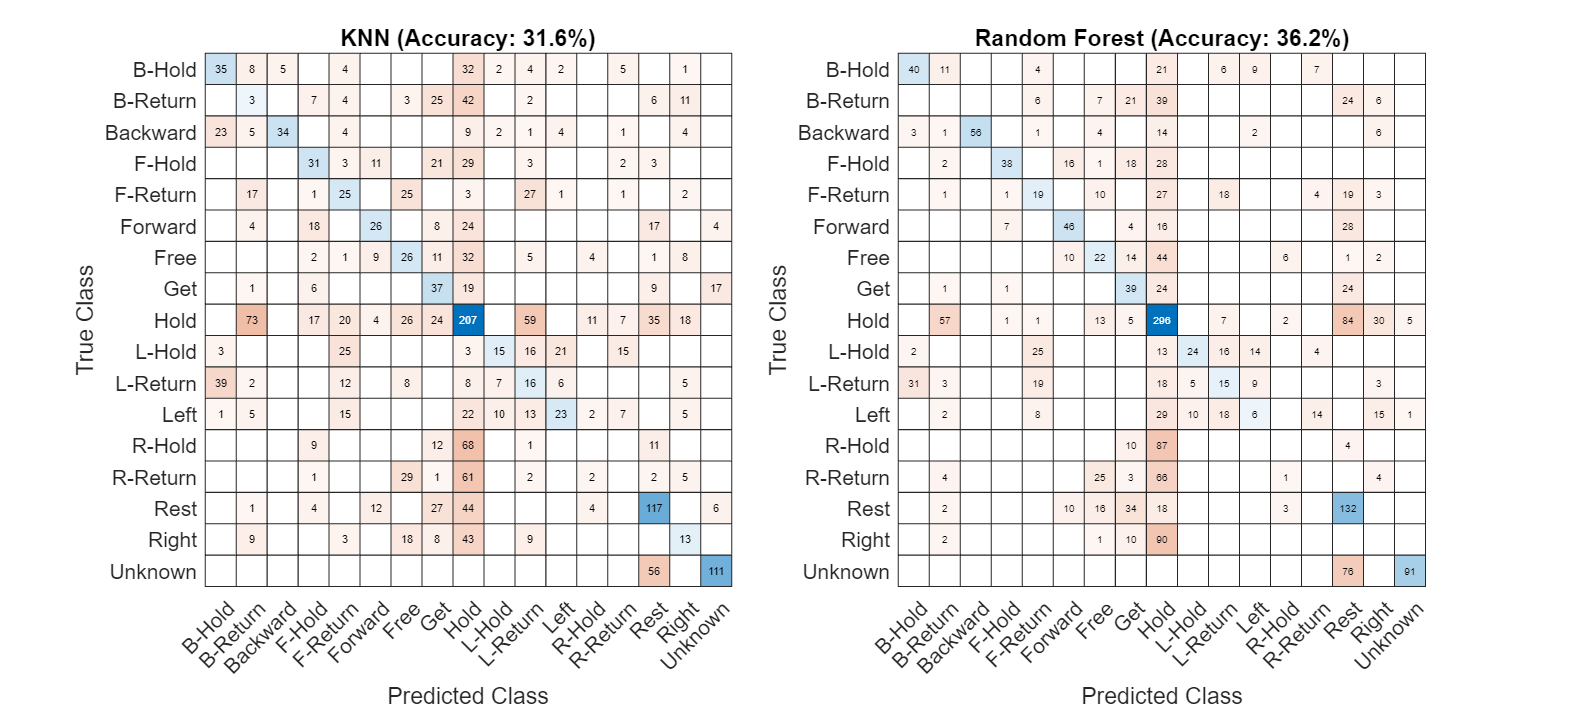


% Plot Confusion Matrices
figure('Name', 'Part E: Confusion Matrices', 'Color', 'w', 'Position', [100 100 1000 450]);

% Subplot 1: KNN
subplot(1,2,1);
confusionchart(Y_test, pred_knn, 'Title', sprintf('KNN (Accuracy: %.1f%%)', acc_knn*100));

% Subplot 2: Random Forest
subplot(1,2,2);
confusionchart(Y_test, pred_rf, 'Title', sprintf('Random Forest (Accuracy: %.1f%%)', acc_rf*100));


fprintf('\n[Part E] Classification completed.\n');


[Part E] Classification completed.


%% Part Y: Improving Accuracy (Adding Features & Feature Normalization)
fprintf('\n[Part Y] Starting Accuracy Improvement...\n');


[Part Y] Starting Accuracy Improvement...


fprintf('Ideas: 1. Adding RMS and SSC features  2. Feature-level Z-score Normalization\n');

Ideas: 1. Adding RMS and SSC features  2. Feature-level Z-score Normalization



all_features_imp = [];
all_labels_imp = [];
all_is_train_imp = [];

% 1. Re-extract features (now 5 features per channel)
for tr = 1:num_trials
    is_train = ismember(tr, train_trials);
    locs = norm_data{1, tr}.comments.locs; 
    labels = norm_data{1, tr}.comments.lables; 
    trial_len = length(norm_data{1, tr}.data);
    
    idx_start = 1;
    while (idx_start + window_samples - 1) <= trial_len
        idx_end = idx_start + window_samples - 1;
        window_center = round((idx_start + idx_end) / 2);
        
        current_label = 'Unknown';
        for k = 1:length(locs)
            if k == length(locs)
                if window_center >= locs(k), current_label = labels{k}; end
            else
                if window_center >= locs(k) && window_center < locs(k+1)
                    current_label = labels{k}; break;
                end
            end
        end
        
        win_features = zeros(1, num_channels * 5); % 5 features per channel
        feat_idx = 1;
        
        for ch = 1:num_channels
            win_data = norm_data{ch, tr}.data(idx_start:idx_end);
            
            % Original Features
            mav = mean(abs(win_data));
            wl = sum(abs(diff(win_data)));
            signs = sign(win_data);
            zc = sum(abs(diff(signs)) > 0);
            
            % NEW Feature: Root Mean Square (RMS)
            rms_val = sqrt(mean(win_data.^2));
            
            % NEW Feature: Slope Sign Change (SSC)
            dv = diff(win_data);
            ssc = sum(dv(1:end-1) .* dv(2:end) < 0);
            
            win_features(feat_idx:feat_idx+4) = [mav, wl, zc, rms_val, ssc];
            feat_idx = feat_idx + 5;
        end
        
        all_features_imp = [all_features_imp; win_features];
        all_labels_imp = [all_labels_imp; string(current_label)];
        all_is_train_imp = [all_is_train_imp; is_train];
        
        idx_start = idx_start + step_samples;
    end
end

% 2. Prepare Train and Test sets
train_idx = all_is_train_imp == 1;
test_idx = all_is_train_imp == 0;

X_train_imp = all_features_imp(train_idx, :); 
Y_train_imp = categorical(all_labels_imp(train_idx));

X_test_imp = all_features_imp(test_idx, :);
Y_test_imp = categorical(all_labels_imp(test_idx));

% 3. Feature Normalization (Z-score on features)
% Calculate mean and std ONLY on training features
mu_feat = mean(X_train_imp);
sigma_feat = std(X_train_imp);
sigma_feat(sigma_feat == 0) = 1; % Avoid division by zero

X_train_imp = (X_train_imp - mu_feat) ./ sigma_feat;
X_test_imp = (X_test_imp - mu_feat) ./ sigma_feat;

fprintf('Extracted %d features per window. Applied Feature Normalization.\n', size(X_train_imp, 2));

Extracted 20 features per window. Applied Feature Normalization.



% 4. Classification with Improved Data
fprintf('\nTraining Improved KNN (k=5)...\n');


Training Improved KNN (k=5)...


mdl_knn_imp = fitcknn(X_train_imp, Y_train_imp, 'NumNeighbors', 5);
pred_knn_imp = predict(mdl_knn_imp, X_test_imp);
acc_knn_imp = sum(pred_knn_imp == Y_test_imp) / length(Y_test_imp);
fprintf('Improved KNN Accuracy: %.2f%%\n', acc_knn_imp * 100);

Improved KNN Accuracy: 31.37%



fprintf('Training Improved Random Forest (50 trees)...\n');

Training Improved Random Forest (50 trees)...


mdl_rf_imp = TreeBagger(50, X_train_imp, Y_train_imp, 'Method', 'classification');
pred_rf_imp = categorical(predict(mdl_rf_imp, X_test_imp));
acc_rf_imp = sum(pred_rf_imp == Y_test_imp) / length(Y_test_imp);
fprintf('Improved Random Forest Accuracy: %.2f%%\n', acc_rf_imp * 100);

Improved Random Forest Accuracy: 40.82%


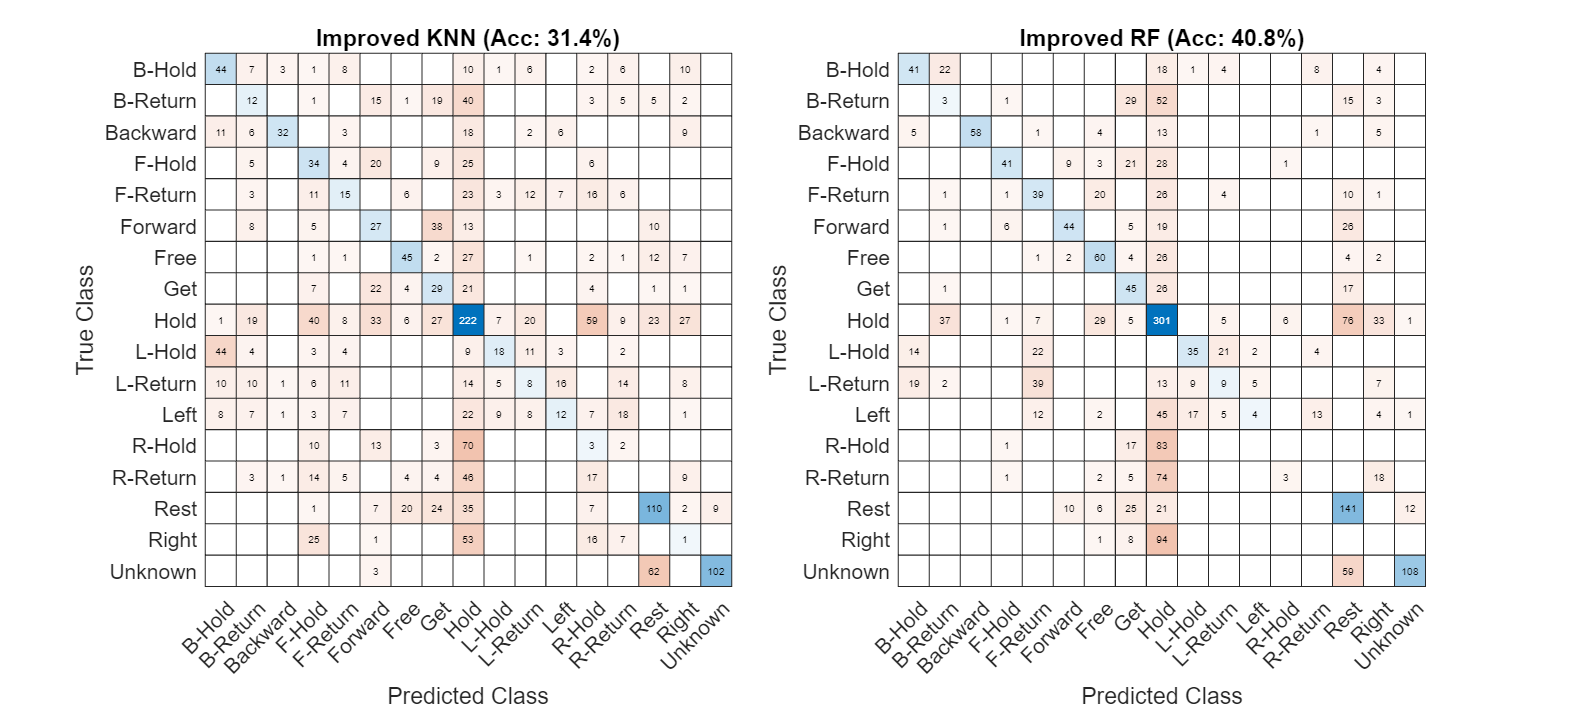


% 5. Plot New Confusion Matrices
figure('Name', 'Part Y: Improved Confusion Matrices', 'Color', 'w', 'Position', [100 100 1000 450]);

subplot(1,2,1);
confusionchart(Y_test_imp, pred_knn_imp, 'Title', sprintf('Improved KNN (Acc: %.1f%%)', acc_knn_imp*100));

subplot(1,2,2);
confusionchart(Y_test_imp, pred_rf_imp, 'Title', sprintf('Improved RF (Acc: %.1f%%)', acc_rf_imp*100));


fprintf('\n[Part Y] Accuracy Improvement completed.\n');


[Part Y] Accuracy Improvement completed.
